# Multi-Robot Lidar Sensor

Copyright 2019 The MathWorks, Inc.

## Overview

The Multi-Robot Lidar Sensor allows you to simulate 2D line-of-sight sensors for visualization and algorithm prototyping of multi-robot environments. This sensor will test for line-of-sight with an occupancy map as well as other robots with finite radius in the environment. It includes a MATLAB and Simulink interface.

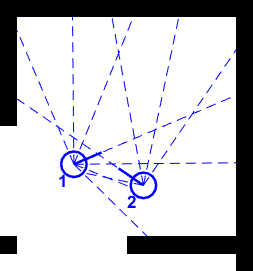

**Properties:**

- **Map: **A [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid)

- **Sensor offset:** A 2-by-1 array of $[x; y]$ offset from the vehicle

- **Scan angles:** An N-by-1 array of scan angles about the $x$-axis, in radians

- **Maximum range:** The sensor maximum range, in meters. Any values outside this range return `NaN`. 

- **Robot index:** The robot index, from 1 to number of robots N

- **Robot radii:** An N-by-1 array of robot radii, in meters (optional)

**Inputs:**

You can attach a `MultiRobotEnv` object so this sensor can be used without inputs by probing into the state of the multi-robot environment. Otherwise, there are up to 2 optional inputs.

- **Poses: **A 3-by-N array representing the robot poses $[x; y; \theta]$, in meters and radians respectively

- **Robot radii:** An N-by-1 array of robot radii, in meters (if the property is left at its default of -1)

**Outputs:**

- **Ranges: **An N-by-1 array of ranges, in meters, corresponding to the **Scan angles** property.

## MATLAB Usage

Create a `MultiRobotLidarSensor` object, set it to a robot index of 3, and configure other sensor properties.

lidar = MultiRobotLidarSensor;
lidar.robotIdx = 3;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,21); % 21 scans from -pi/2 to +pi/2
lidar.maxRange = 4

lidar =   MultiRobotLidarSensor with properties:

         mapName: ''
    sensorOffset: [0 0]
      scanAngles: [-1.5708 -1.4137 -1.2566 -1.0996 -0.9425 -0.7854 -0.6283 -0.4712 -0.3142 -0.1571 0 0.1571 0.3142 0.4712 0.6283 0.7854 0.9425 1.0996 1.2566 1.4137 1.5708]
        maxRange: 4
        robotIdx: 3
      robotRadii: -1


Attach the sensor to a 5-robot environment. The environment contains an example map and all robot radii are 0.5 meters.

numRobots = 5;
env = MultiRobotEnv(numRobots);
load exampleMap
env.mapName = 'map';
env.robotRadius = 0.5*ones(5,1);
env.hasWaypoints = false;
attachLidarSensor(env,lidar);

Simulate the lidar and plot the ranges given the map and vehicle pose.

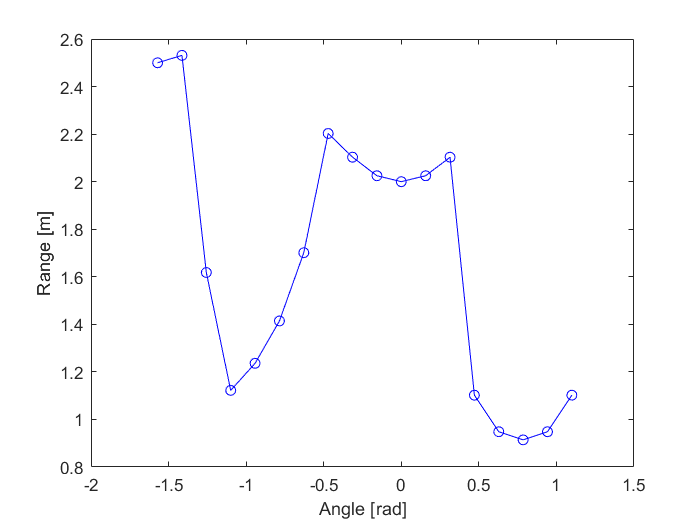

env.Poses = [1 1 0;2 2 0;3 3 0;4 4 0;5 5 0]';
ranges = lidar();
plot(lidar.scanAngles,ranges,'bo-');
xlabel('Angle [rad]')
ylabel('Range [m]')

Visualize using the Multi-Robot Visualizer.

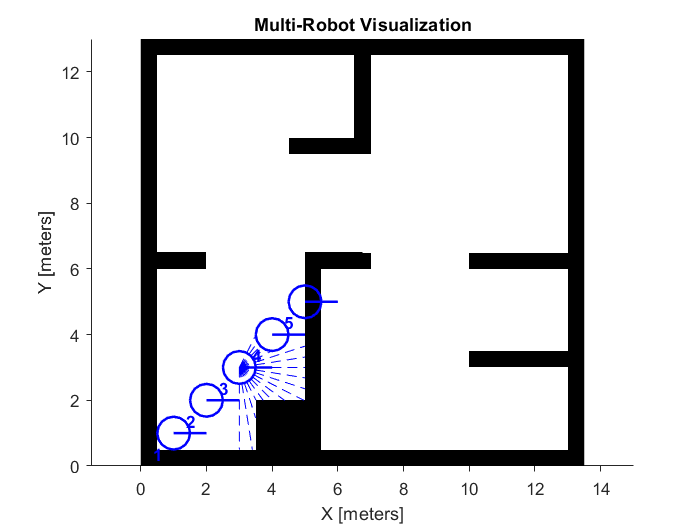

allRanges = cell(1,numRobots);
allRanges{3} = ranges;
env(1:numRobots,env.Poses,allRanges)

**Examples**

- [Multirobot lidar sensor MATLAB example](matlab:edit mrsMultiRobotLidar)

## Simulink Usage

Use the **Multi-Robot Lidar Sensor** block from the **Environments** section of the [block library](matlab:mobileRoboticsLib). 

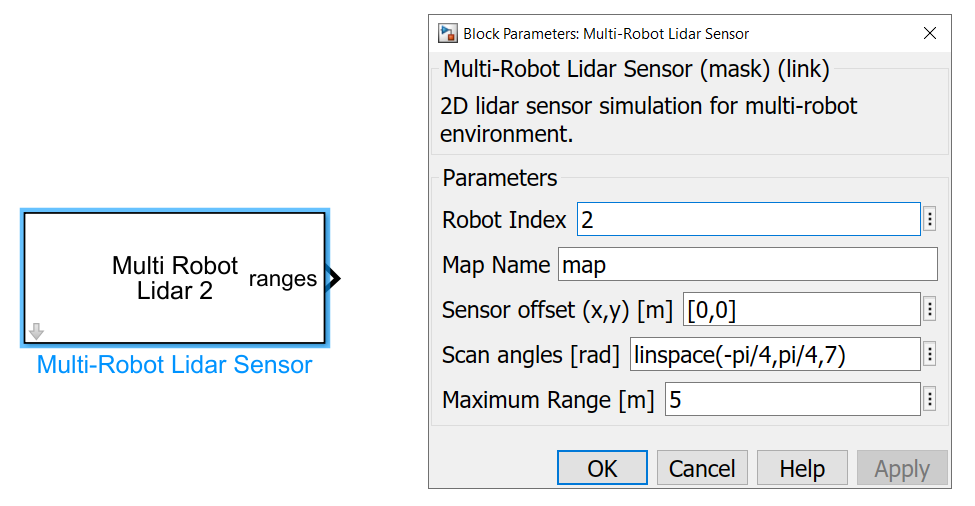

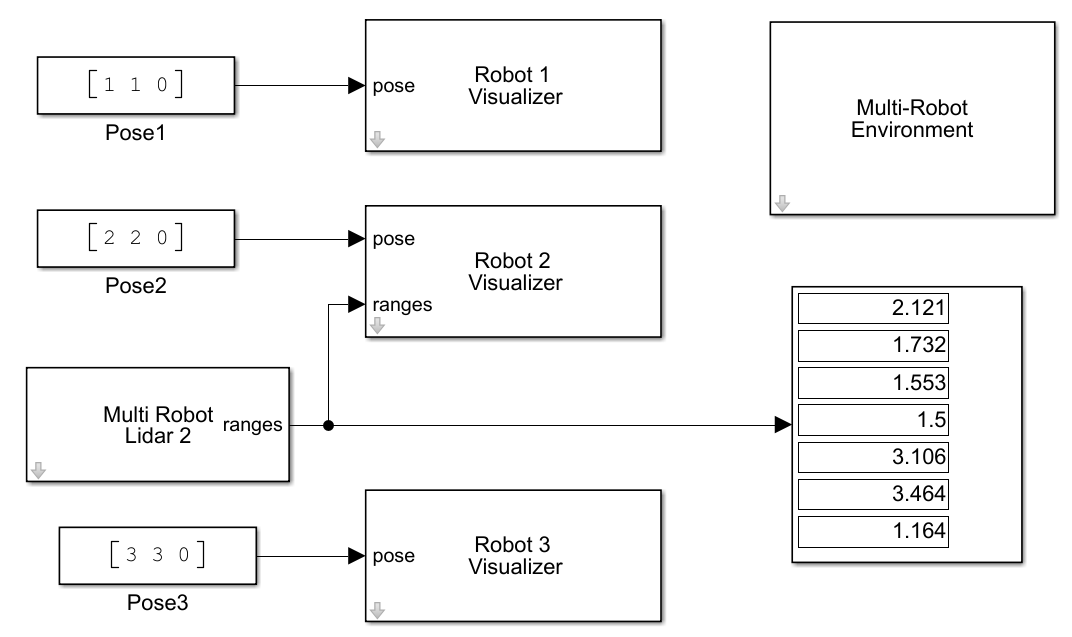

**Examples**

- [Multi-Robot Sensor Example](matlab:mrsMultiRobotSensorModel)

- [Multi-Robot Obstacle Avoidance Example](matlab:mrsMultiRobotAvoidance)